fname = 'Fig1h_kymo_all_tracks_global_ringtype_iMedFilt_VerCINI data.csv';
data= importdata(fname);

T=abs(data.data(:,2));
S=abs(data.data(:,3));
Diam=data.data(:,7);
isNascent=logical(data.data(:,8));

T_N=T(isNascent);%nascent
S_N=S(isNascent);
T_MC=T(~isNascent);%mature or constricting
S_MC=S(~isNascent);

dataLabel=cell(size(isNascent));
dataLabel(isNascent==1)={'Nascent'};
dataLabel(isNascent~=1)={'Mature/Constrincting'};

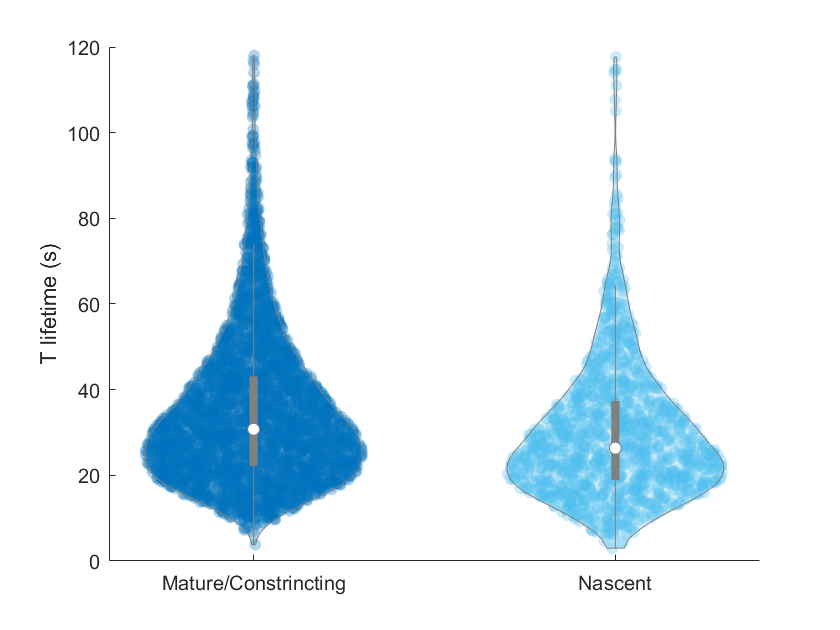

figure;
violinplot(T,dataLabel);
ylabel('T lifetime (s)');

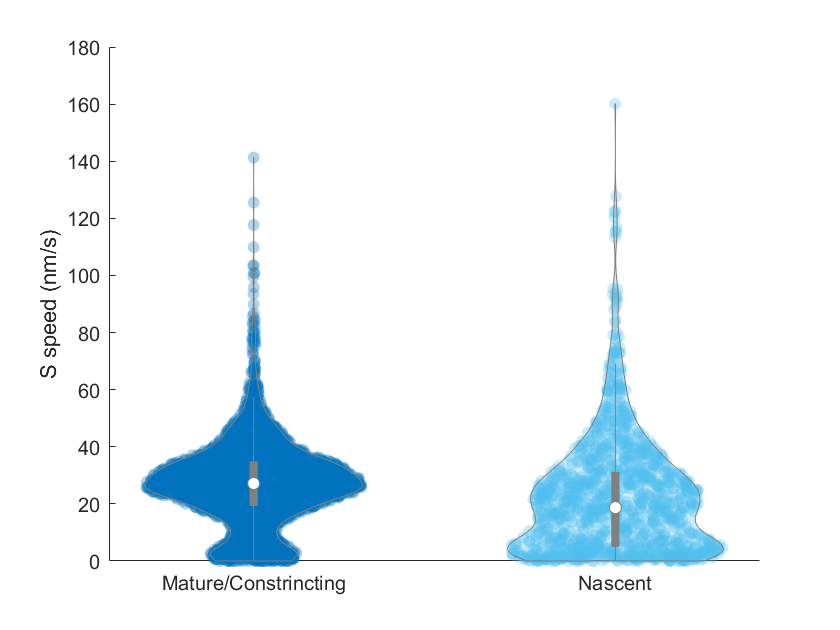


figure;
violinplot(S,dataLabel);
ylabel('S speed (nm/s)')

%try the 2d KDE
numel(find(S_N<=10))/numel(S_N)%static motile fraction have to get this right

ans = 0.3508


%unbounded support, normal distribution
[f,xi] = ksdensity(dataN,'Kernel','normal');

Fmat=reshape(f,[30,30]);
gridT=reshape(xi(:,1),[30,30]);
gridS=reshape(xi(:,2),[30,30]);
sum(Fmat(:))

ans = 0.0309

sum(Fmat(gridS<=10))/sum(Fmat(:))

ans = 0.3766

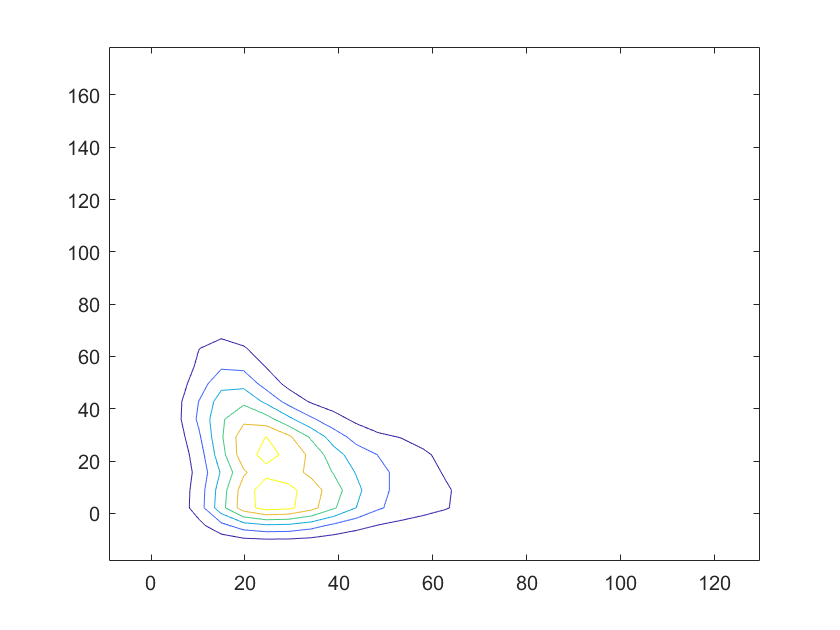

figure;
contour(gridT,gridS,Fmat);

%unbounded support, epanechnikov distribution
[f,xi,bw] = ksdensity(dataN,'Kernel','epanechnikov');
bw

bw =     3.9815    6.0778


Fmat=reshape(f,[30,30]);
gridT=reshape(xi(:,1),[30,30]);
gridS=reshape(xi(:,2),[30,30]);
sum(Fmat(:))

ans = 0.0340

sum(Fmat(gridS<=10))/sum(Fmat(:))

ans = 0.3014

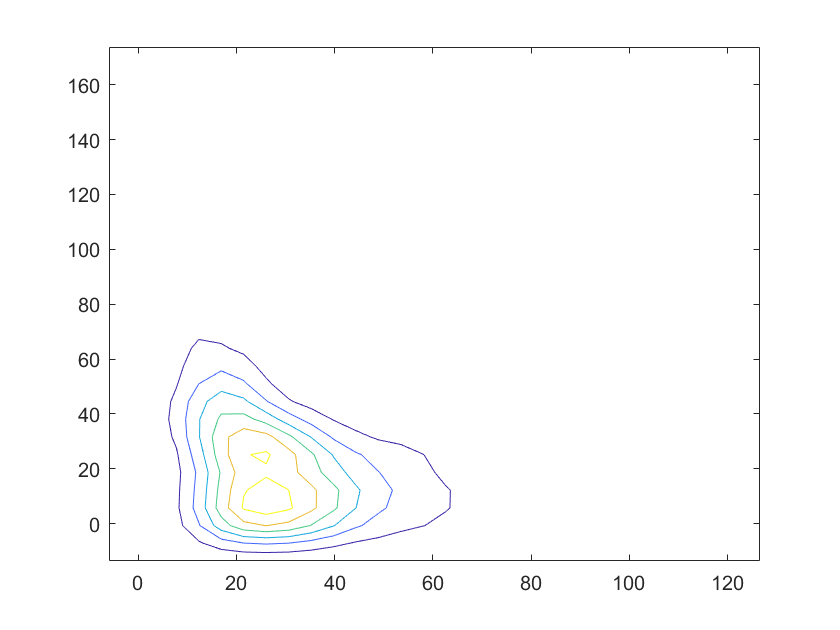

figure;
contour(gridT,gridS,Fmat);

%unbounded support, epanechnikov distribution, finer bandwidth
[f,xi,bw] = ksdensity(dataN,'Kernel','epanechnikov','Bandwidth',bw*0.1);

Fmat=reshape(f,[30,30]);
gridT=reshape(xi(:,1),[30,30]);
gridS=reshape(xi(:,2),[30,30]);
sum(Fmat(:))

ans = 0.0436

sum(Fmat(gridS<=10))/sum(Fmat(:))

ans = 0.2935

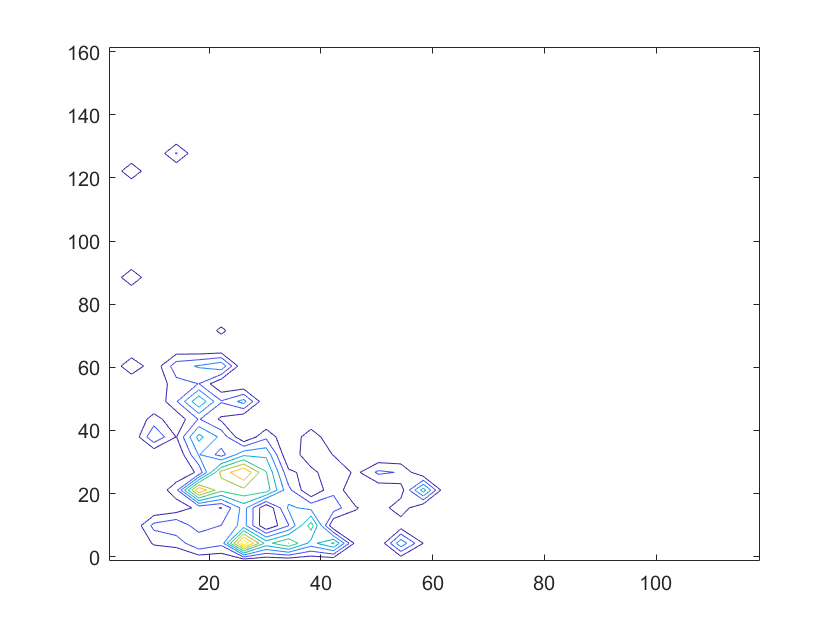

figure;
contour(gridT,gridS,Fmat);


%positive support only
dataN=[T_N,S_N];
dataN(dataN==0)=eps;%replace zero valueswith minimum positive
bw=[4,6]*1;
[f,xi,bw] = ksdensity(dataN,'Support','positive','BoundaryCorrection','reflection','Kernel','epanechnikov','Bandwidth',bw);
bw

bw =      4     6



Fmat=reshape(f,[30,30]);
gridT=reshape(xi(:,1),[30,30]);
gridS=reshape(xi(:,2),[30,30]);
sum(Fmat(:))

ans = 0.0341

sum(Fmat(gridS<=10))/sum(Fmat(:))

ans = 0.2134

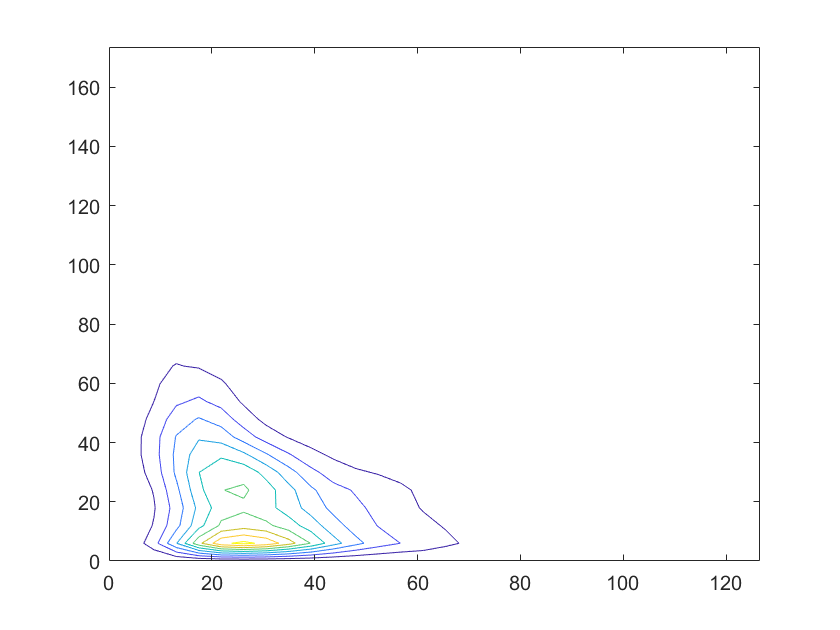

figure;
contour(gridT,gridS,Fmat);

numel(find(S_N<=10))/numel(S_N)

ans = 0.3508

positive support only should be better but for some reason it's getting the density estimate wrong, ie fractions of static immobile do not match underlying data